clear
close all
targetImage = im2double(imread("dogdogorange.png"));

imagefiles = dir("data64\cat\*.jpg");
filepath = "data64\cat"

filepath = "data64\cat"


rTileSize = 64;
oTileSize = 8;
tileRatio = oTileSize/rTileSize*4;
nrOfPrimaryColours = 5;

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 109

tileCols = ceil(cols / oTileSize)

tileCols = 88

ans =       421896       29819       13579       18423       95730       23126        1239        2764        1179           8           4


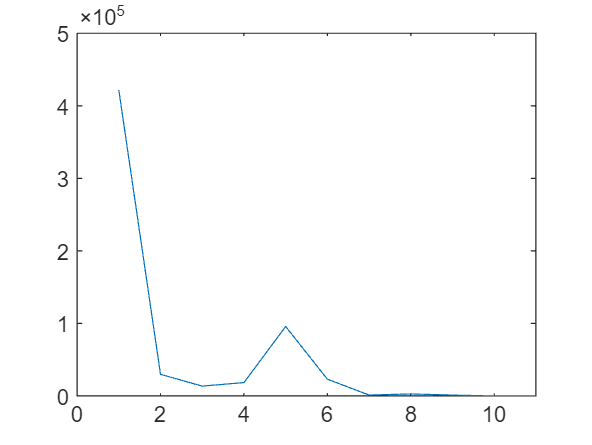

ans =     0.7176    0.2549    0.7137    0.4157    0.2824
    0.6314    0.2706    0.5961    0.3686    0.3098
    0.5569    0.2275    0.4784    0.2588    0.2706
    0.6942    0.1575    0.0491    0.0381    0.0303



outputImage = zeros(tileRows*rTileSize*tileRatio, tileCols*rTileSize*tileRatio,3);
%outputImage = zeros(tileRows*rTileSize, tileCols*rTileSize,3);

processbar = waitbar(0, 'Loading Images...');
numberOfImages = 5000%15165

numberOfImages = 5000

for ii=1:numberOfImages
    waitbar(ii/numberOfImages, processbar, "Loading Images...");
    currentfilename = imagefiles(ii).name;
    currentimage = im2double(imread(filepath + "\" +  currentfilename));
    %currentimage = imresize(currentimage, tileRatio);
    images{ii, 1} = currentimage;
    images{ii, 2} = getImportantColours(currentimage, nrOfPrimaryColours);
end
close(processbar)

images{1,2}

ans =     0.8549    0.6078    0.8431    0.1686    0.2667
    0.8588    0.4980    0.8471    0.1020    0.1961
    0.8392    0.4863    0.8275    0.0235    0.1412
    0.7019    0.1519    0.0627    0.0310    0.0178


processbar = waitbar(0, 'Load Colours...');
for c = 1:tileCols 
    waitbar(c/tileCols, processbar, "Load Colours...");
    for r = 1:tileRows       
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);
        wantedTiles{r,c} = currentTile;
        targetPrimaryColours = getImportantColours(currentTile, nrOfPrimaryColours);
        [~, cMax] = size(targetPrimaryColours);
        for colour = 1:cMax
            targetColours{r, c, colour} = targetPrimaryColours(:,colour);
        end
    end
end
close(processbar)

threshold = 12;
%processedImages = preprocessImages3(images, targetColours, threshold, tileRatio, nrOfPrimaryColours);
processedImages = preprocessImages2(images, threshold, tileRatio);

ans = 5000


%processedImages = images
[datasetSize, ~] = size(processedImages)

datasetSize = 200

processbar = waitbar(0, 'Processing Images...');
addedImages = [];
tic
% go through each tile
for c = 1:1:tileCols
    waitbar(c/tileCols, processbar, "bonking kitties...");
    for r = 1:1:tileRows       
        tileRFrom = 1 + (r-1)*(rTileSize * tileRatio);
        tileRTo = r*rTileSize* tileRatio;
        tileCFrom = 1 + (c-1)*(rTileSize* tileRatio);
        tileCTo = c*rTileSize* tileRatio;

        currentTile = wantedTiles{r,c};
        
        for colour = 1:(nrOfPrimaryColours)
            colours = targetColours{r,c,colour};
            targetPrimaryColours(:, colour) = colours;
        end

        lowerDeltaEImages = {}; %holds index value to processed images        
        bestImageIndex = 0;
        bestDelta = 9999;
        imageFound = false;
        % find best image for each tile
        for i = 1:datasetSize     
            curImg = processedImages{i,1};
            %processColours = processedImages{i,2}
            currentPrimaryColours = processedImages{i,2};

            if comparePrimaryColours(targetPrimaryColours, currentPrimaryColours, threshold)
                bestImageIndex = i;
                lowerDeltaEImages{end+1} = i;
                imageFound = true;
            end

            
            %curImg = processedImages{i,1};
            %currentPrimaryColours = processColours;
            %currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
            %if currentDelta < bestDelta
            %    bestImageIndex = i;
            %    bestDelta = currentDelta;
            %end
        end
        %Subsampling
        subsamplesAmt = 16;      
        subsampledTargetTile = subsampleImage(currentTile, subsamplesAmt);
        
        % till loop för att checka L skillnad i 3x3
        smallestMSE = 9999;
        %length(lowerDeltaEImages)
        for q = 1:length(lowerDeltaEImages)
            subsampledCurrentImage = subsampleImage(processedImages{lowerDeltaEImages{q}}, subsamplesAmt);
            MSE = subsampledCmp(subsampledTargetTile, subsampledCurrentImage, subsamplesAmt);
            MSE = MSE + rand * 100;
            if(MSE < smallestMSE)
                smallestMSE = MSE;
                bestImageIndex = lowerDeltaEImages{q};
            end
        end
        % if we have not found a cat add the best cat
        if isempty(lowerDeltaEImages)
            bestDelta = 9999;
            
            for i = 1:datasetSize
                curImg = processedImages{i,1};
                currentPrimaryColours = processedImages{i,2};
                currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
                if currentDelta < bestDelta
                    bestImageIndex = i;
                    bestDelta = currentDelta;
                end
            end
        end
        %tileRFrom = 1 + (r-1)*(rTileSize);
        %tileRTo = r*rTileSize;
        %tileCFrom = 1 + (c-1)*(rTileSize);
        %tileCTo = c*rTileSize;
        
        imageToAdd = processedImages{bestImageIndex,1};
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = imageToAdd;
    end   
end
toc

Elapsed time is 1626.657678 seconds.


close(processbar)

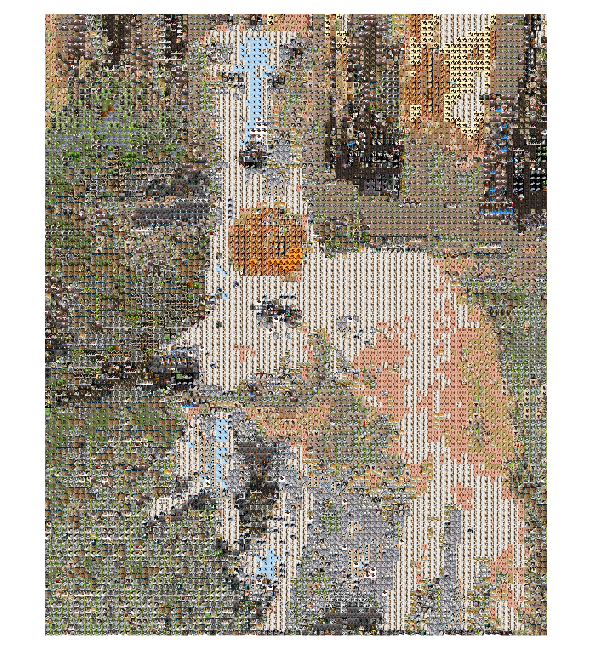

imshow(outputImage)

outputImage

outputImage = outputImage(:,:,1) =

    0.8992    0.8877    0.8726    0.8858    0.8883    0.9031    0.9181    0.9015    0.8724    0.8632    0.8596    0.8641    0.8662    0.8723    0.8556    0.8299    0.8551    0.8877    0.9028    0.8978    0.8926    0.8863    0.8806    0.8811    0.8667    0.8938    0.8875    0.8614    0.8493    0.8475    0.8623    0.8707    0.7534    0.8050    0.8342    0.8424    0.8384    0.8222    0.8117    0.5875    0.4250    0.7099    0.7577    0.7433    0.7318    0.6905    0.6832    0.7023    0.8057    0.9419    0.9952    0.9927    0.9781    0.9142    0.8008    0.7427    0.7745    0.8564    0.8575    0.8039    0.7634    0.7483    0.7675    0.8189    0.6653    0.6630    0.6859    0.7007    0.6548    0.6801    0.7031    0.7005    0.6915    0.6697    0.6521    0.6504    0.6690    0.7068    0.7110    0.6933    0.6784    0.6847    0.6929    0.6887    0.6817    0.6746    0.6640    0.6294    0.6310    0.6255    0.6058    0.6244    0.6257    0.5939    0.5777    0.5628    

Objective Comparisons

% S-CIELAB: Measures perceptual color differences with spatial filtering.
%scale output image to original size to comapre
outputImageResized = imresize(outputImage, size(targetImage(:,:,1)),"bicubic");
imwrite(outputImage, 'primColourDogNoDep.png');
%check same size
disp(size(outputImageResized));

   867   701     3



disp(size(targetImage));

   867   701     3




outputImageXYZ = rgb2xyz(outputImageResized);
targetImageXYZ = rgb2xyz(targetImage);


%calc PPI
screenHeight = 1440; %pixels
screenWidth = 2560; %pixels
hypPix = hypot(screenWidth, screenHeight);
hypInch = 27; %diagonal size (inches)
ppi = hypPix / hypInch;

d = 16; % ~40 cm 
sampPerDeg = ppi * d * tan(pi/180); % spd = ppi * avstånd till bild i inches * tan(pi/180)
CIED65samp = [95.05, 100, 108.9];

%full reference metric
scielabVal = scielab(sampPerDeg, outputImageXYZ, targetImageXYZ, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...



scielabAvg = mean(mean(scielabVal));
disp(['Average scielab value: ', num2str(scielabAvg)]);

Average scielab value: 1.4375


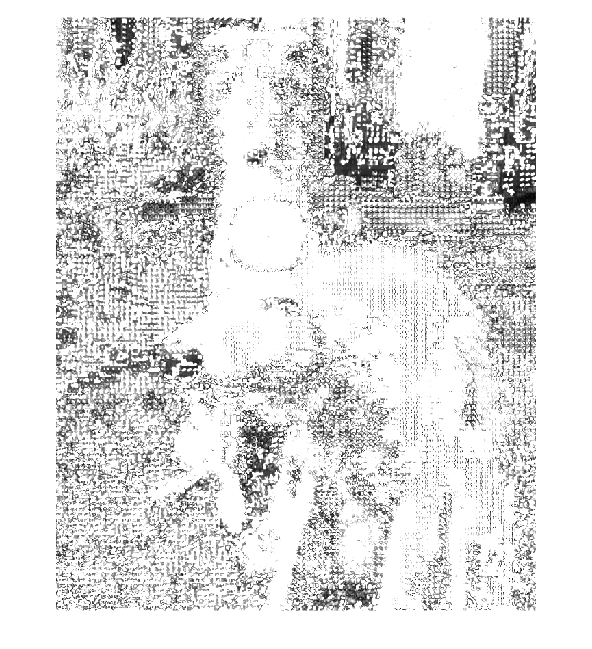

imshow(scielabVal)



% SSIM: Evaluates structural similarity based on luminance, contrast, and structure.
[dist2val, dist2map] = ssim(targetImage, outputImageResized);
disp(['SSIM Value: ', num2str(dist2val)]);

SSIM Value: 0.18063


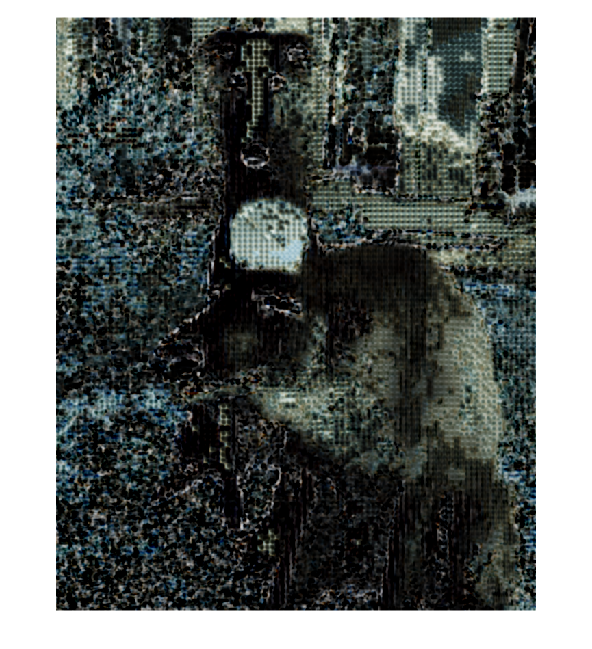

imshow(dist2map)

%imwrite(dist2map, 'dist2mapdark1nopre.png')

% PSNR: Quantifies the signal-to-noise ratio, useful for overall image fidelity.
psnrVal = psnr(targetImage, outputImageResized);
disp(['PSNR Value: ', num2str(psnrVal), ' dB']);

PSNR Value: 13.9249 dB
